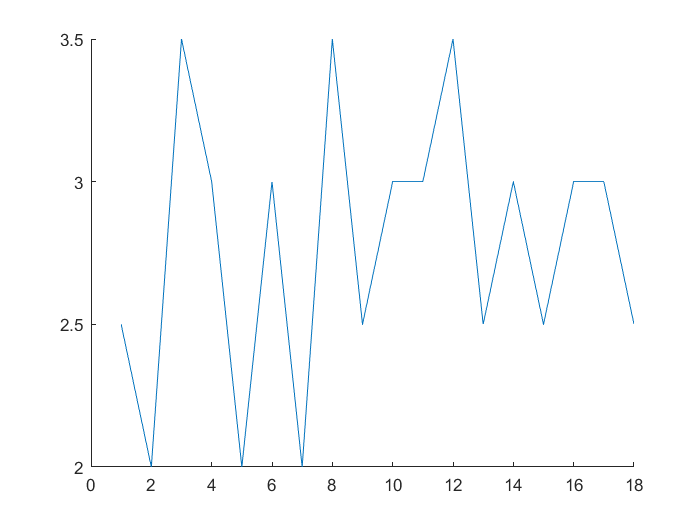

clear
clc
close all

% insert the address for the file location
load 'E:\LEARN\S3\DEIS\Labs\lab4\Lab_Students(1)\Lab_Students\ProblemNo1\ProblemNo1.mat'

t=1:18;

h=figure('Name','Distance Kalman Filter');hold on;
plot(t,Distance);


A=1;
H=1;

Q=0.40;
R=1;
for jj=1:length(t)

    % initial condition
    if(jj==1)
        P=25;   
        x=0.3;
    end
    
    % measurement from the signal
    z=Distance(1,jj);
    xp = A*x;
    Pp = A*P*A' + Q;
    
    K = Pp*H'*inv(H*Pp*H' + R);
    
    x = xp + K*(z - H*xp);
    P = Pp - K*H*Pp;
    
    Distance_Kalman(jj,1)=x;
end

## Plot function should be implemented here

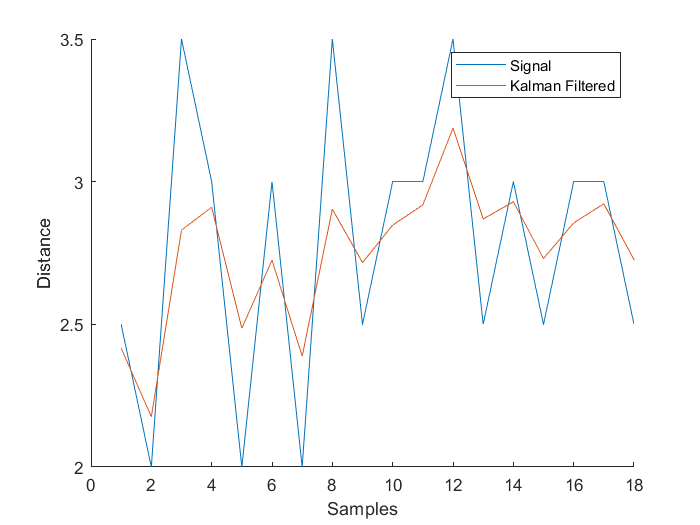

plot(t, Distance_Kalman); 

xlabel('Samples');  

ylabel('Distance'); 

legend('Signal','Kalman Filtered');